# How to read in and analyze single device, multi session snirf data in Matlab

Here, we  investigate how to read in data saved in [**snirf format**](https://github.com/fNIRS/snirf/) and process those data with [**Homer3**](https://github.com/BUNPC/Homer3). The dataset we present here was recorded using a [**Brite MKII (Artinis Medical Systems B.V., Elst, The Netherlands)**](https://www.artinis.com/brite). The optodes of the Brite were placed over the right prefrontal and parietal cortex, with Channel Rx7-Tx10 being positioned over the hand/finger area of the motor cortex

The subject was sitting in a chair with his arm on a table and was instructed to fingertap at certain moments in time. The experiment started with a resting period of approximately 30 seconds, during which the participants had a fixation cross, relax and was instructed not to move. The resting period was followed by a fingertapping period lasting 20 seconds during which the participant was instructed to fingertap. These two periods were repeated 10 times. 

## Defining helper variables

We define three variables *fname1*, *fname2*, and *fname3* containing the location of the data files used in this livescript. In addition, we define two variables *transmitter_id* and *receiver_id* containing the transmitter and receiver IDs (Rx7-Tx10) of the channel positioned over the motor cortex. Another variable (*dpf*) is defined containing the differential pathlength factor (DPF) used in modified Beer-Lambert law. The last variable defined is *trange* which contains the pre-stimulus and post-stimulus durations of block averaging in seconds.

datadir = 'single_device_finger_tapping';
fname1 = fullfile(datadir, 'Brite Fingertapping 5-12-2020.snirf');
fname2 = fullfile(datadir, 'Brite Fingertapping 5-15-2020.snirf');
fname3 = fullfile(datadir, 'Brite Fingertapping 5-19-2020.snirf');

transmitter_id = 10;
receiver_id = 7;
dpf = 6.06;
trange = [-5, 30];

## Homer 3

From here on, we start using [**Homer3**](https://github.com/BUNPC/Homer3) functions. You need to make sure to add the respective functions that we need to your Matlab path (e.g. using the [**addpath**](https://www.mathworks.com/help/matlab/ref/addpath.html) command). 

We use the following paths / functions:

Located in Homer3\DataTree\AcquiredData\Snirf\:

- [*SnirfClass*](https://github.com/BUNPC/Homer3/blob/master/DataTree/AcquiredData/Snirf/SnirfClass.m) to read in the snirf file

Located in Homer3\FuncRegistry\UserFunctions:

- [*hmrR_Intensity2OD*](https://github.com/BUNPC/Homer3/blob/master/FuncRegistry/UserFunctions/hmrR_Intensity2OD.m) to convert raw data into ODs

- [*hmrR_BandpassFilt*](https://github.com/BUNPC/Homer3/blob/master/FuncRegistry/UserFunctions/hmrR_BandpassFilt.m) to bandpass filter the data

- [*hmrR_OD2Conc*](https://github.com/BUNPC/Homer3/blob/master/FuncRegistry/UserFunctions/hmrR_OD2Conc.m) to convert ODs to (relative change in) concentrations 

- [*hmrR_BlockAvg*](https://github.com/BUNPC/Homer3/blob/master/FuncRegistry/UserFunctions/hmrR_BlockAvg.m) to compute the trial/block average per session

Eventually, we loop through our three datasets to compute the average across sessions and plot those.

## Loading the data files

We load the data files of the three sessions of fingertapping experiment using the SnirfClass. 

acquired1 = SnirfClass(fname1);
acquired2 = SnirfClass(fname2);
acquired3 = SnirfClass(fname3);

## Converting intensity to optical density

We convert the intensity signals of the three data files loaded to optical densities (ODs). 

dod1 = hmrR_Intensity2OD(acquired1.data); 
dod2 = hmrR_Intensity2OD(acquired2.data); 
dod3 = hmrR_Intensity2OD(acquired3.data); 

## Filtering

The ODs are fitered by using a band-pass filter [0.01-0.1] Hz such that the frequency of the hemodynamic response remains and frequencies of other signal components are filtered out.

dod1 = hmrR_BandpassFilt(dod1, 0.01, 0.1);
dod2 = hmrR_BandpassFilt(dod2, 0.01, 0.1);
dod3 = hmrR_BandpassFilt(dod3, 0.01, 0.1);

## Converting optical density to concentration

We convert the filtered ODs of the three data files to concentration changes in oxygenated hemoglobin (HbO) and deoxygenated hemoglobin (HbR) signals by using the modifed Beer-Lambert law. 

dc1  = hmrR_OD2Conc(dod1, acquired1.probe, [dpf, dpf]);
dc2  = hmrR_OD2Conc(dod2, acquired2.probe, [dpf, dpf]);
dc3  = hmrR_OD2Conc(dod3, acquired3.probe, [dpf, dpf]);

## Block averaging

In this step, we compute the average of fingertapping trials across one specific channel in each session. First, the resulting concentration data files (*dc1*, *dc2*, *dc3*) are updated in order to only include the HbO, HbR, and HbT (total hemoglobin) signals of the desired channel (Rx7-Tx10). Next, the average of fingertapping trials (*acquiredX.stim(1)*; *X=1,2,3*) starting 5 seconds before the desired events (pre-stimulus) and ending 30 seconds after them (post-stimulus) is computed in each session. 

for idx=1:numel(dc1.measurementList)
    s_id0 = dc1.measurementList(1, idx).sourceIndex;  
    d_id0 = dc1.measurementList(1, idx).detectorIndex; 
    if(s_id0 == transmitter_id && d_id0 == receiver_id)
        HbO_id = idx;
        break;
    end
end

dc1.measurementList = dc1.measurementList(1, HbO_id:HbO_id+2);
dc1.dataTimeSeries  = dc1.dataTimeSeries(:, HbO_id:HbO_id+2);
dc2.measurementList = dc2.measurementList(1, HbO_id:HbO_id+2);
dc2.dataTimeSeries  = dc2.dataTimeSeries(:, HbO_id:HbO_id+2);
dc3.measurementList = dc3.measurementList(1, HbO_id:HbO_id+2);
dc3.dataTimeSeries  = dc3.dataTimeSeries(:, HbO_id:HbO_id+2);


[dcAvgSubjs1, ~, ~, ~] = hmrR_BlockAvg(dc1, acquired1.stim(1), trange);
[dcAvgSubjs2, ~, ~, ~] = hmrR_BlockAvg(dc2, acquired2.stim(1), trange);
[dcAvgSubjs3, ~, ~, ~] = hmrR_BlockAvg(dc3, acquired3.stim(1), trange);

## Computing the grand average

We compute the grand average (*HbO_avg* and *HbR_avg*) of the three sessions during fingertapping trials across the specified channel (Rx7-Tx10). 

HbO1 = dcAvgSubjs1.dataTimeSeries(:,1);
HbR1 = dcAvgSubjs1.dataTimeSeries(:,2);
HbO2 = dcAvgSubjs2.dataTimeSeries(:,1);
HbR2 = dcAvgSubjs2.dataTimeSeries(:,2);
HbO3 = dcAvgSubjs3.dataTimeSeries(:,1);
HbR3 = dcAvgSubjs3.dataTimeSeries(:,2);

time = dcAvgSubjs1.time;

HbO_avg = (HbO1+HbO2+HbO3)/3;
HbR_avg = (HbR1+HbR2+HbR3)/3;

HbO_avg_micro = HbO_avg * 1e6;
HbR_avg_micro = HbR_avg * 1e6;


## Plotting

Here, we plot the resulting grand average HbO and HbR signals in micromol, shown in red and blue, respectively, using standard Matlab functions.  

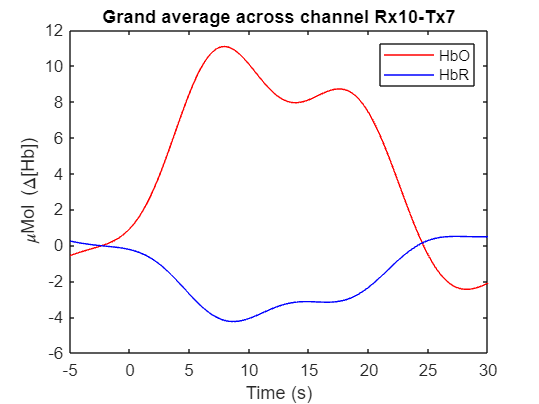

figure;
plot(time, HbO_avg_micro,'r');
hold on;
plot(time, HbR_avg_micro, 'b')
xlabel('Time (s)')
ylabel('\muMol (\Delta[Hb])')
legend('HbO', 'HbR')
title(sprintf('Grand average across channel Rx%d-Tx%d', transmitter_id, receiver_id));